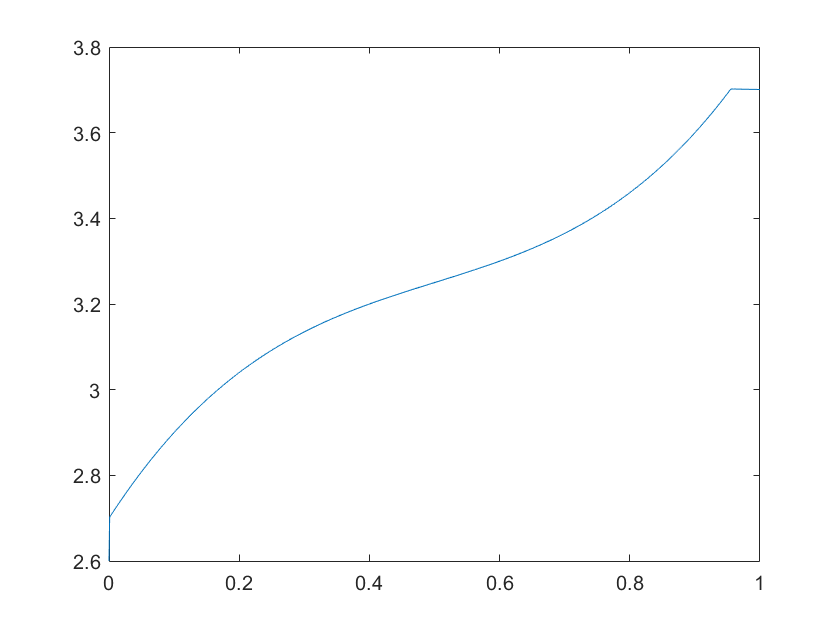

%Requirement 3+4
%In terms of hours

Vmax=3.7;
chargeRate=[.1, .2, .5, 1, 1.5, 2];
U=1;
R=0.1;
t=[0:0.001:1];
I=zeros(length(t),1);
V=zeros(length(t),1);
x=zeros(length(t),1);

Vmax=3.7;
Imax=1;

    V(1)=2.6;
    I(1)=Imax;
    x(1)=0;
    
    for i=2:length(t)
        I(i)=cccv(x(i-1),Imax,Vmax);
        x(i)=x(i-1)+(I(i)/1000);
        V(i)=(2.6+2.35*x(i)-3.75*x(i)^2+2.5*x(i)^3)+R*I(i);
    end
    
  plot(t, V)

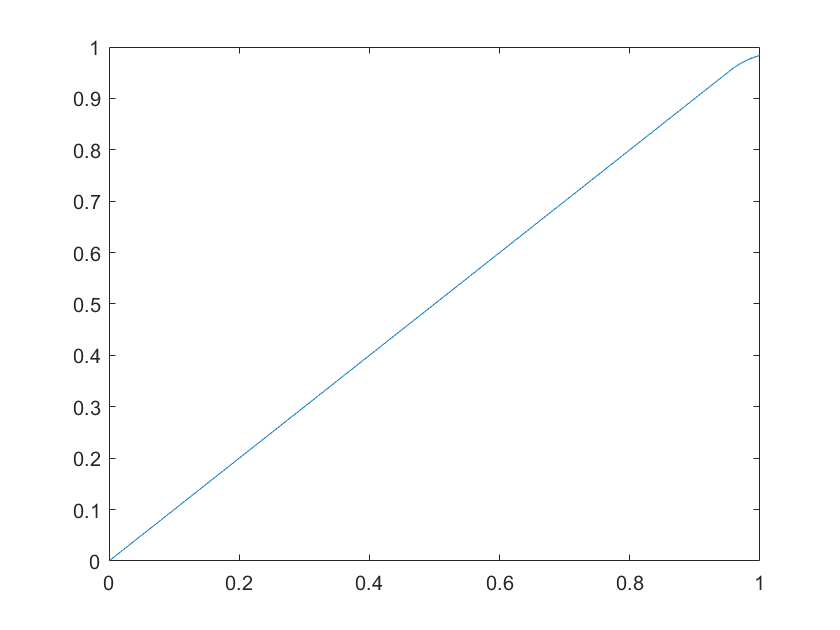

  plot(t, x)

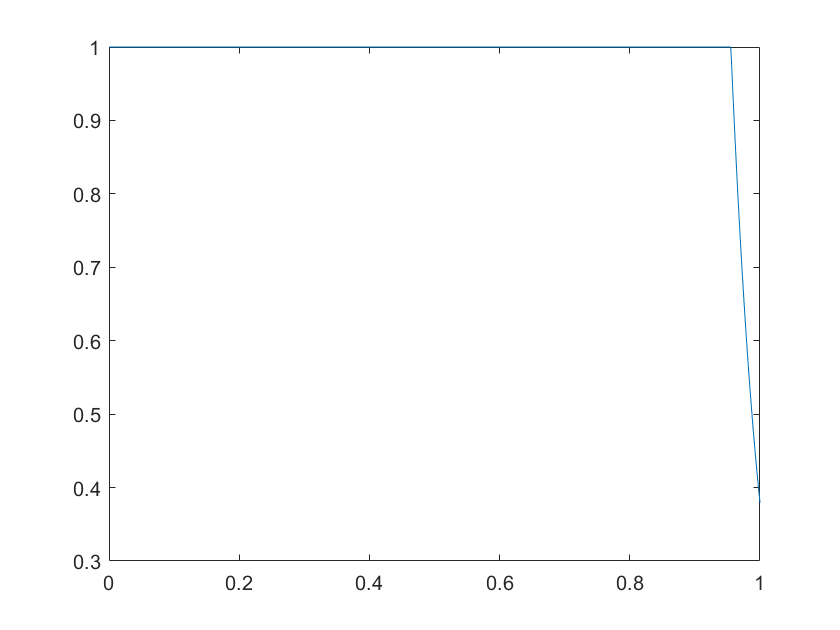

  plot(t,I)